# ME5554/AOE5754/ECE5754 Applied Linear Systems

# Homework 5

Md Riasat Morshed Khan

10/14/2024

## Problem 1.

a)  Define a state-space LTI object associated with the SISO ODE below, where $u$ is the input and $y$ is the output.  You may either first generate an LTI transfer function, then convert to state-space, or you may derive a canonical state-space form directly.


$$\ddot{y} +10\left(\dot{y} -\dot{u} \right)+26\left(y-u\right)=42\dot{u} +442u$$


clear; clc; close all;
A = [0 1;-26 -10];
B = [0 0;468 52];
% Typically, for a SISO system, the output y=x1, which corresponds to the
% first state variable, not the identity matrix for C
C = [1 0];
D = []; %since it's a SISO system
ss_obj = ss(A,B,C,D);
transferFunc = tf(ss_obj)


transferFunc =
 
  From input 1 to output:
        468
  ---------------
  s^2 + 10 s + 26
 
  From input 2 to output:
        52
  ---------------
  s^2 + 10 s + 26
 
Continuous-time transfer function.
Model Properties


b)  Use the `DCGAIN` function to compute the DC gain of this open-loop system.

k = dcgain(ss_obj)

k =     18     2


c)  Use the `FREQRESP` function to compute the DC gain of this open-loop system.

% DC gain is the magnitude of the frequency response at omega = 0
DC_gain = freqresp(ss_obj,0)

DC_gain =     18     2


d)  Use the `DAMP` function to compute and display the poles, damping ratios, natural frequencies, and time constants of this open-loop system.

[wn,zeta,p] = damp(ss_obj)

wn =     5.0990
    5.0990


zeta =     0.9806
    0.9806


p =   -5.0000 + 1.0000i
  -5.0000 - 1.0000i


e)  Use the transfer function coefficients to compute the poles and zeros.  Also compute the natural frequencies (units of Hz), damping ratios, and time constants of the poles.

polesFromTF = roots(double(cell2sym(transferFunc.Denominator(1))))

polesFromTF =   -5.0000 + 1.0000i
  -5.0000 - 1.0000i


zerosFromTF = roots(double(cell2sym(transferFunc.Numerator(1))))


zerosFromTF =

  0×1 empty double column vector





wn = abs(polesFromTF);  % Natural frequencies (rad/s)
zeta = -real(polesFromTF) ./ wn  % Damping ratios

zeta =     0.9806
    0.9806



% Convert natural frequencies to Hz (from rad/s)
wn_Hz = wn / (2 * pi)

wn_Hz =     0.8115
    0.8115



% Compute time constants
timeConstants = -1 ./ real(polesFromTF)  % Time constants

timeConstants =     0.2000
    0.2000


## Problem 2.

a)  Use the `FREQRESP` function to compute the frequency response for the dynamic system in Problem 1.  You must define a logarithmic frequency range (i.e. `LOGSPACE`) that includes **one decade above the highest and one decade below the lowest** pole and/or zero frequencies.  Plot the dB magnitude vs. log frequency (Hz), and the phase (degrees) vs. log frequency (Hz).  Do NOT use one of the built-in Matlab functions like `LTIVIEW` or `BODE` to generate the plots.  Mark the locations of the open-loop poles and zeros on the plots using `XLINE`.  Properly label all axes and include a grid on all plots.


freq_rangeHz = [abs(polesFromTF);abs(zerosFromTF)] ./ (2*pi);
minFreqHz_lim = min(freq_rangeHz)/10;
maxFreqHz_lim = max(freq_rangeHz)*100;

freqHz = logspace(log10(minFreqHz_lim),log10(maxFreqHz_lim),200);
H = squeeze(freqresp(transferFunc,2*pi*freqHz));
dB_all = 20.* log10(H);
deg_all = rad2deg(angle(H));

poles_Hz = abs(polesFromTF) / (2 * pi);
zeros_Hz = abs(zerosFromTF) / (2 * pi);

figure()
subplot(2,1,1);
semilogx(freqHz, dB_all, 'LineWidth', 2);

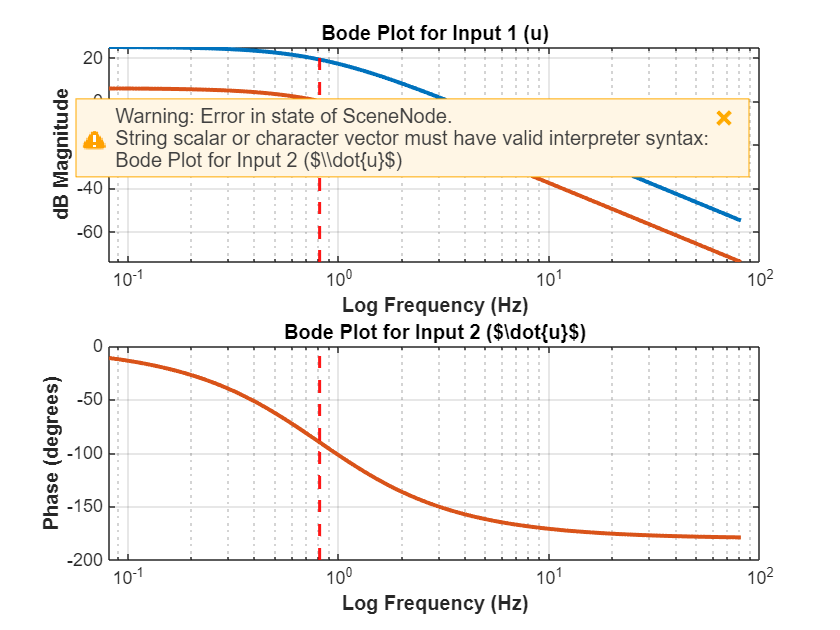

hold on;
semilogx(freqHz, ones(1, length(freqHz)) * -3, 'k--', 'LineWidth', 2);  % Corrected the plot of -3 dB line
ylabel('dB Magnitude', 'FontSize', 10, 'FontWeight', 'bold');
xlabel('Log Frequency (Hz)', 'FontSize', 10, 'FontWeight', 'bold');
title('Bode Plot for Input 1 (u)', 'FontSize',10,'FontWeight','bold')
xline(poles_Hz, 'r--', 'LineWidth', 1.5);  % Corrected xline syntax for poles
grid on;

subplot(2,1,2);
semilogx(freqHz, deg_all, 'LineWidth', 2);
ylabel('Phase (degrees)', 'FontSize', 10, 'FontWeight', 'bold');
xlabel('Log Frequency (Hz)', 'FontSize', 10, 'FontWeight', 'bold');
title('Bode Plot for Input 2 ($\dot{u}$)', 'FontSize',10,'FontWeight','bold')
xline(poles_Hz, 'r--', 'LineWidth', 1.5);  % Corrected xline syntax for poles
grid on;

b)  Use the FRF data to generate a numerical steady-state harmonic response of this system to a sinusoidal excitation at 8 Hz.  Also use the LSIM function to generate a numerical response to the same excitation at 8 Hz.  Confirm that the harmonic and the LSIM responses are the same in steady-state by plotting both on the same properly annotated axes.

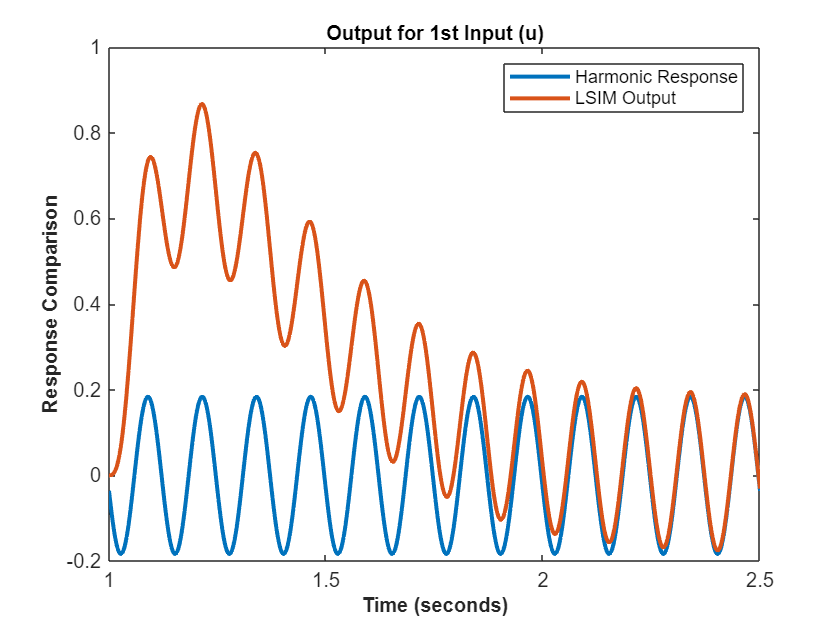

U = 1;
jwHz = 8;
time = linspace(1,2.5,1000);
H_jw = squeeze(freqresp(transferFunc,2*pi*jwHz));
yp_1 = U * abs(H_jw(1)) * sin(2*pi*jwHz * time + angle(H_jw(1)));
yp_2 = U * abs(H_jw(2)) * sin(2*pi*jwHz * time + angle(H_jw(2)));
% by lsim function
[y_lsim_1,time] = lsim(ss_obj(1,1),sin(2*pi*jwHz * time),time); % I have two inputs so i need to make it single output
[y_lsim_2,time] = lsim(ss_obj(1,2),sin(2*pi*jwHz * time),time);
figure()
plot(time(:,1), yp_1(1,:), 'LineWidth',2);
hold on
plot(time(:,1),y_lsim_1(:,1), 'LineWidth',2)
ylabel('Response Comparison', 'FontSize', 10, 'FontWeight', 'bold');
xlabel('Time (seconds)', 'FontSize', 10, 'FontWeight', 'bold');
title('Output for 1st Input (u)','FontSize', 10, 'FontWeight', 'bold')
legend('Harmonic Response','LSIM Output');

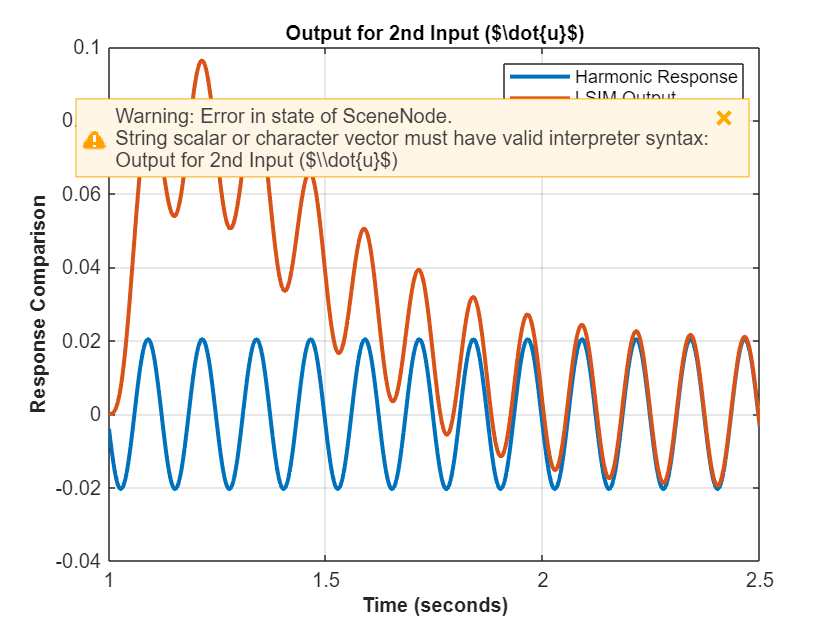

figure()
plot(time(:,1),yp_2(1,:), 'LineWidth',2);
hold on 
plot(time(:,1),y_lsim_2(:,1), 'LineWidth',2);
grid on
ylabel('Response Comparison', 'FontSize', 10, 'FontWeight', 'bold');
xlabel('Time (seconds)', 'FontSize', 10, 'FontWeight', 'bold');
title('Output for 2nd Input ($\dot{u}$)','FontSize', 10, 'FontWeight', 'bold')
legend('Harmonic Response','LSIM Output');
grid on

## Problem 3.

a)  Determine the natural frequency, damping ratio, and the corresponding pole locations such that a 2nd order system has exactly 1.5165% overshoot, and a 5% settling time of exactly 624.11 milliseconds for a step input.  You may use Matlab to perform the computations, but you will have to look up the formulas for 2nd order systems (any undergraduate controls textbook!) and incorporate those into your Matlab code.  


$$t_{5%} =-\frac{\ln \left(0\ldotp 05\right)}{\;\xi \;\omega \;}\approx \frac{3}{\;\xi \;\omega \;}$$


This has to be less than 0.62411s


$$\begin{array}{l}
\mathrm{Real}\;\mathrm{part}\;\mathrm{of}\;\mathrm{the}\;\mathrm{pole}=\xi \;\omega >\frac{3}{0\ldotp 62411}\;\frac{\mathrm{rad}}{s}=4\ldotp 8s\;\\
\Rightarrow -\xi \;\omega <-4\ldotp 8\;s\;
\end{array}$$



$$\mathrm{PO}\left\lbrack %\right\rbrack =100\;e^{-\left(\left.\frac{\xi \;\pi \;\;}{\sqrt{\;1-\xi {\;}^{2\;} }}\;\right)\right)}$$
 
$$\begin{array}{l}
\Rightarrow 1\ldotp 5165=100\;e^{-\left(\left.\frac{\xi \;\pi \;\;}{\sqrt{\;1-\xi {\;}^{2\;} }}\;\right)\right)} \\
\Rightarrow \xi =0\ldotp 8
\end{array}$$


Now, let $\xi =0\ldotp 8,\mathrm{therefore},\omega >6\frac{\mathrm{rad}}{s}$.

Let, $\omega =6\ldotp 25\;\frac{\mathrm{rad}}{s}\;\mathrm{if}\;\xi \omega =5$    


$$\begin{array}{l}
s_{1\;} =-5+6\ldotp 25*\sqrt{\left(1-0\ldotp 8^{2\;} \right)\;=-1\ldotp 25}\\
\;s_2 =-5-6\ldotp 25*\sqrt{\left(1-0\ldotp 8^{2\;} \right)\;=-8\ldotp 75}
\end{array}$$


b)  Use the `POLY` function to construct a characteristic polynomial associated with these two poles, then use the `DAMP` function in Matlab to validate that you have achieved the correct damping ratio and natural frequency.  Note that the documentation for `DAMP` only describes its use for an LTI object input; however, you can also input a vector of polynomial coefficients.

zeta = 0.8;
omega_n = 6.25;
s1 = -5 + 6.25*sqrt(1-0.8^2);
s2 = -5 - 6.25*sqrt(1-0.8^2);
char_poly = poly([s1, s2]);

[wn, zeta_damped, poles_out] = damp(char_poly)

wn =     8.7500
    1.2500


zeta_damped =      1
     1


poles_out =    -8.7500
   -1.2500


## Problem 4.

Determine three desired closed-loop (CL) eigenvalues to meet the following requirements:

- The dominant CL pole has a time constant of exactly 5 milliseconds

- The second real CL pole is exactly 3 times faster than the dominant CL pole

- The third real CL pole is exactly 5 times faster than the dominant CL pole


$$\begin{array}{l}
\frac{1}{\zeta \omega \;}=0\ldotp 005s\\
\mathrm{First}\;\mathrm{pole}\;=-\zeta \omega =-\frac{1}{0\ldotp 005}=200s\\
\mathrm{Second}\;\mathrm{Pole}=-\zeta \omega =-\frac{1}{\frac{0\ldotp 005}{3}}=600s\\
\mathrm{Third}\;\mathrm{Pole}=-\zeta \omega =-\frac{1}{\frac{0\ldotp 005}{5}}=1000s
\end{array}$$


Construct the closed-loop Characteristic polynomial associated with these desired closed-loop poles.

s1_4 = -200;
s2_4 = -600;
s3_4 = -1000;

CED_4 =            1        1800      920000   120000000



CED_4 = poly([s1_4,s2_4,s3_4])

## Problem 5.

Given the following open-loop dynamic system:


$$A=\left\lbrack \begin{array}{cc}
-4 & -1\\
26 & -6
\end{array}\right\rbrack ,\;B=\left\lbrack \begin{array}{c}
1\\
0
\end{array}\right\rbrack$$


a)  Determine the open-loop natural frequencies and damping ratios.

A_5 = [-4 -1; 26 -6];
B_5 = [1; 0];
C_5 = [];
D_5 = [];


wn_5 =     7.0711
    7.0711


zeta_damped_5 =     0.7071
    0.7071


ss_obj_5 = ss(A_5,B_5,C_5,D_5);
[wn_5, zeta_damped_5, ~] = damp(ss_obj_5)

s1_5 = -14.1421 + 6.6139i

s2_5 = -14.1421 - 6.6139i

b)  Solve for the full state feedback gains such that the closed-loop poles have natural frequencies that are twice the natural frequency of the open loop system, and a closed-loop damping ratio of 0.8839.  Check your result.

s1_5 = -wn_5(1)*2 + 1j *wn_5(1)*2 * sqrt(1-0.8839^2)
s2_5 = -wn_5(1)*2 - 1j *wn_5(1)*2 * sqrt(1-0.8839^2)

syms s g1 g2 
G = [g1 g2];
sI_A_BG = s*eye(2) - ss_obj_5.a + ss_obj_5.b*G;
CE_5 = collect(det(sI_A_BG),s);
CED_5 = poly([s1_5,s2_5]);
LHS_5 = [1 0; 6 26];
RHS_5 = [CED_5(2)-10;CED_5(3)-50];
G_5 = (inv(LHS_5)*RHS_5)';

ans =  -14.1421 + 6.6139i
 -14.1421 - 6.6139i


% checking the result
eig(ss_obj_5.a-ss_obj_5.b*G_5)

## Problem 6.

Given the following open-loop dynamic system:


$$A=\left\lbrack \begin{array}{ccc}
-10 & 18 & 0\\
-9 & 8 & 0\\
-9 & 5 & 3
\end{array}\right\rbrack ,\;B=\left\lbrack \begin{array}{c}
1\\
1\\
0
\end{array}\right\rbrack$$


Choose a set of desired closed-loop eigenvalues that meet the following requirements:

- All closed-loop poles must have the same natural frequency of 20 rad/sec

- The closed-loop complex poles must have a damping ratio that is 7.2443 times larger than the open-loop complex pole damping ratio

- All closed-loop poles must be stable

Apply the brute force method from L8 to compute the full state feedback control gains that place the closed-loop poles at the desired locations.

A_6 = [-10 18 0;-9 8 0;-9 5 3];
B_6 = [1;1;0];
C_6 = [];
D_6 = [];

ss_obj_6 = ss(A_6,B_6,C_6,D_6);
[wn_6, zeta_damped_6, poles_out_6] = damp(ss_obj_6);
 
wn_6_cl = 20;
zeta_6_cl = 7.2443 * zeta_damped_6(2);

s1_6 = -wn_6_cl + 1j * wn_6_cl * sqrt(1-zeta_6_cl^2);
s2_6 = -wn_6_cl - 1j * wn_6_cl * sqrt(1-zeta_6_cl^2);
s3_6 = -wn_6_cl*zeta_6_cl;

syms s g1 g2 g3
G_6 = [g1 g2 g3];
sI_A_BG_6 = s*eye(3) - ss_obj_6.a + ss_obj_6.b*G_6;
CE_6 = collect(det(sI_A_BG_6),s);

G_6 =    77.1890  -20.1890 -131.8247


CED_6 = poly([s1_6,s2_6,s3_6]);
LHS_6 = [1 1 0; 7 -2 -4; -30 -3 -85]; %hardcoded

ans =  -20.0000 +12.0000i
 -20.0000 -12.0000i
 -16.0000 + 0.0000i


RHS_6 = [CED_6(2)+1;CED_6(3)-76;CED_6(4)+246];
G_6 = (inv(LHS_6)*RHS_6)'
% checking the result
eig(ss_obj_6.a-ss_obj_6.b*G_6)

## Problem 7.

For the SISO state-space realization given by:


$$A=\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
0 & 0 & 1\\
-52 & -30 & -4
\end{array}\right\rbrack ,\;B=\left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack ,\;C=\left\lbrack \begin{array}{ccc}
20 & 1 & 0
\end{array}\right\rbrack ,\;D=\left\lbrack \begin{array}{c}
0
\end{array}\right\rbrack$$


a)  Apply the brute force method from L8 to compute the full state feedback control gains that place the closed-loop poles at the desired locations  from Problem 4

A_7 = [0 1 0;0 0 1;-52 -30 -4];
B_7 = [0;0;1];
C_7 = [20 1 0];
D_7 = 0;

ss_obj_7 = ss(A_7,B_7,C_7,D_7);
[wn_7, zeta_damped_7, poles_out_7] = damp(ss_obj_7);
% Values from Problem 4
s1_7 = -200;
s2_7 = -600;
s3_7 = -1000;


$$CE\_7 = s^{3}+\left(g_{3}+4\right)\,s^{2}+\left(g_{2}+30\right)\,s+g_{1}+52$$

syms s g1 g2 g3

CED_7 =            1        1800      920000   120000000


G_7 = [g1 g2 g3];
sI_A_BG_7 = s*eye(3) - ss_obj_7.a + ss_obj_7.b*G_7;
CE_7 = collect(det(sI_A_BG_7),s)

G_7 =    119999948      919970        1796


CED_7 = poly([s1_7,s2_7,s3_7])
LHS_7 = [0 0 1;0 1 0;1 0 0]; %hardcoded

ans = 1.0e+03 *

   -0.2000
   -0.6000
   -1.0000


RHS_7 = [CED_7(2)-4;CED_7(3)-30;CED_7(4)-52];
G_7 = (inv(LHS_7)*RHS_7)'

b)  Validate your result in Matlab by computing the eigenvalues of the closed-loop state matrix.

eig(ss_obj_7.a-ss_obj_7.b*G_7)